## Problem 11.3

Note: I added an initial guess (x0) because it is impossible to ascertain the dimension of x from the function handle H.

function [x, iter] = sdsolve(H, b, x0, tol, maxiter)
    x = x0;
    r = b - H(x);
    for iter = 1:maxiter
        if norm(r)/norm(b) < tol
            break;
        end
        q = H(r);
        a = (r'*r)/(r'*q);
        x = x + a * r;
        if mod(iter, 50) == 0
            r = b - H(x);
        else
            r = r - a*q;
        end
    end
end

Provided image convolution function:

% imconv.m
%
% Convolves a square image with a square kernel
%
% Written by: Justin Romberg, Georgia Tech
% Created: 11/17/2011

function Y = imconv(X, W)
N = size(X, 1);
K = size(W, 1);
Y = ifft2(fft2(X,N+K-1,N+K-1).*fft2(W,N+K-1,N+K-1));
end

Provided image convolution inverse function:

% imconv_transpose.m
%
% Convolves a square image with the "flipped" version of the square kernel,
% and takes the middle part.
%
% This is the adjoint of imconv.m.
%
% Written by: Justin Romberg, Georgia Tech
% Created: 11/17/2011

function V = imconv_transpose(Y, W)
M = size(Y, 1);
K = size(W, 1);
N = M - K + 1;
Vu = ifft2(fft2(Y,N+2*K-2,N+2*K-2).*fft2(rot90(W,2) ,N+2*K-2,N+2*K-2));
V = Vu(K:N+K-1,K:N+K-1);
end

The steepest descent algorithm recovers the original image within a relative error of ${10}^{-4}$ in 599 steps.

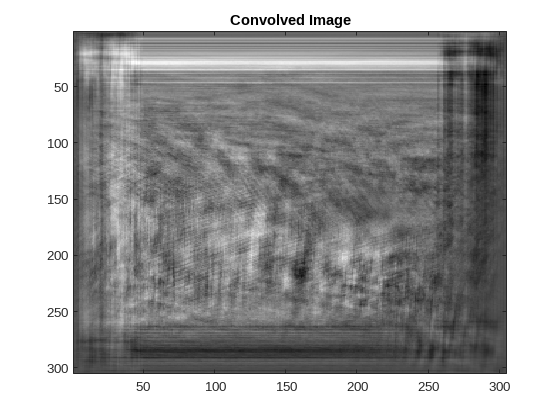

load imagedeconv_data

A = @(z) reshape(imconv(reshape(z,N,N), W), (N+K-1)^2, 1);
At = @(z) reshape(imconv_transpose(reshape(z, N+K-1, N+K-1), W), N^2, 1);
AtA = @(z) At(A(z));

y = reshape(Y, (N+K-1)^2, 1);

imagesc(Y); colormap("gray"); title("Convolved Image");

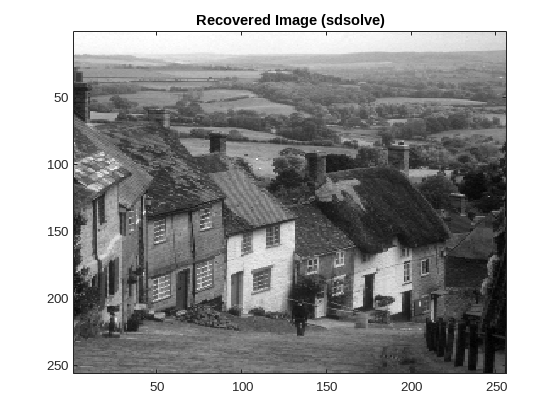

[x, iter] = sdsolve(AtA, At(y), zeros(N*N, 1), 10^-4, 10000);

x_sc = reshape(x, N, N);
imagesc(x_sc); colormap("gray"); title("Recovered Image (sdsolve)");

fprintf("Original image found in %d steps w/ steepest descent\n", iter);

Original image found in 599 steps w/ steepest descent


## Problem 11.4

Note: I added an initial guess (x0) because it is impossible to ascertain the dimension of x from the function handle H.

function [x, iter] = cgsolve(H, b, x0, tol, maxiter)
    x = x0;
    r = b - H(x);
    d = r;
    for iter = 1:maxiter
        if norm(r)/norm(b) < tol
            break;
        end
        a = (r'*r)/(d'*H(d));
        x = x + a * d;
        if mod(iter, 50) == 0
            r1 = b - H(x);
        else
            r1 = r - a*H(d);
        end
        beta = (r1'*r1)/(r'*r);
        d = r1 + beta * d;
        r = r1;
    end
end

The conjugate gradient descent algorithm recovers the original image within a relative error of ${10}^{-4}$ in 77 steps.

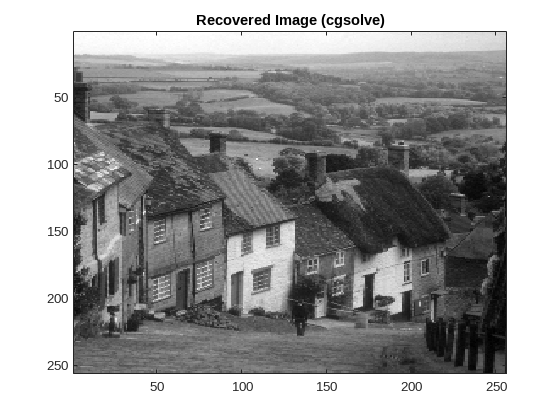

load imagedeconv_data

A = @(z) reshape(imconv(reshape(z,N,N), W), (N+K-1)^2, 1);
At = @(z) reshape(imconv_transpose(reshape(z, N+K-1, N+K-1), W), N^2, 1);
AtA = @(z) At(A(z));

y = reshape(Y, (N+K-1)^2, 1);

[x, iter] = cgsolve(AtA, At(y), zeros(N*N, 1), 10^-4, 10000);
x_cg = reshape(x, N, N);
imagesc(x_cg); colormap("gray"); title("Recovered Image (cgsolve)");

fprintf("Original image found in %d steps w/ conjugate gradients\n", iter);

Original image found in 77 steps w/ conjugate gradients


## Problem 11.5

function plotFaces(X,numPerLine,numLines)

faceW = 32; 
faceH = 32; 

Y = zeros(faceH*numLines,faceW*numPerLine); 
for i=0:numLines-1 
  	for j=0:numPerLine-1 
    	 Y(i*faceH+1:(i+1)*faceH,j*faceW+1:(j+1)*faceW) = reshape(X(:,i*numPerLine+j+1),[faceH,faceW]); 
  	end 
end 

figure()
imagesc(Y);
colormap(gray);
axis off;
axis equal;
end

*Part A* - Write a function to find the optimal affine approximation to the data in faces:

function [Q, theta] = myPCA(X, r)
    sample_mean = mean(X, 2);
    x_tilde = X - sample_mean;
    [Q, ~, ~] = svd(x_tilde);
    Q = Q(:, 1:r);
    theta = Q'*x_tilde(:, 1:r);
end

Plot original 16 faces along with the approximation:

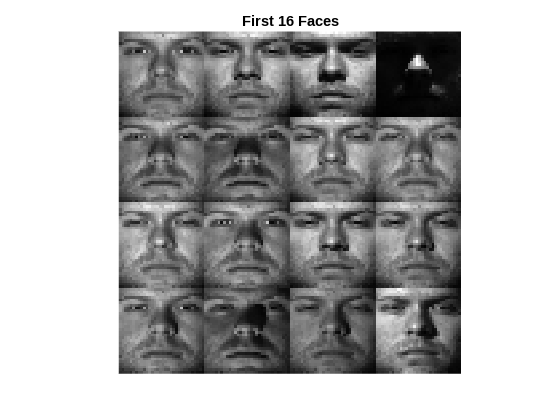

load faces

plotFaces(faces, 4, 4); title("First 16 Faces");

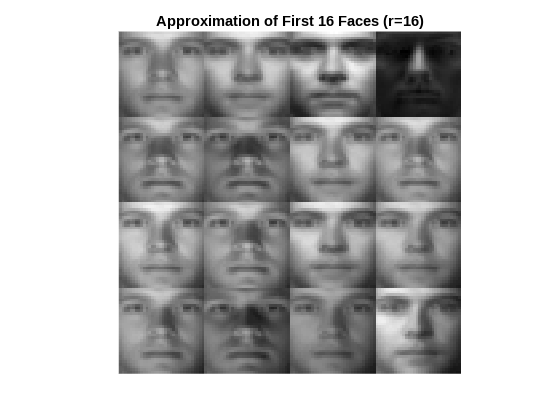


r = 16;
[Q, theta] = myPCA(faces, r);
x_hat = sample_mean + Q * theta;
plotFaces(x_hat, 4, 4); title("Approximation of First 16 Faces (r=16)");

*Part B* - Plot each of the basis vectors identified in Part A:

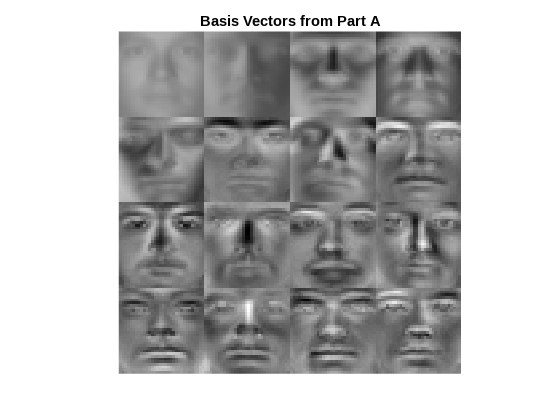

plotFaces(Q, 4, 4); title("Basis Vectors from Part A");

*Part C* - Determine the minimum value of r such that the relative error is less than 5 percent:

To maintain an error less than 5 percent, r must be greater than or equal to 190. This means that the first 190 singular values of faces account for 95% of the features in the first 16 entries.

for i = 16:2414
    [Q, theta] = myPCA(faces, i);
    x_hat = sample_mean + Q * theta;
    if (norm(x_hat(:, 1:16) - faces(:, 1:16), 'fro')/norm(faces(:, 1:16), 'fro') * 100 < 5)
        break;
    end
end
fprintf("Minimum value of r such that relative error is less than 5 percent: %d", i);

Minimum value of r such that relative error is less than 5 percent: 190

*Part D* - Comment on the qualitiative differences between the original dataset and the approximation as r varies:

The larger r is, the more accurate the approximation gets. As r decreases, the approximations become more smooth, appearing like an average of all of the faces. Only the particularly prominant "face-like" features are captured in the approximation.